# Loading simulations data

clc; clear;
load("Analysis.mat")

## Plotting the retrievals of a memory

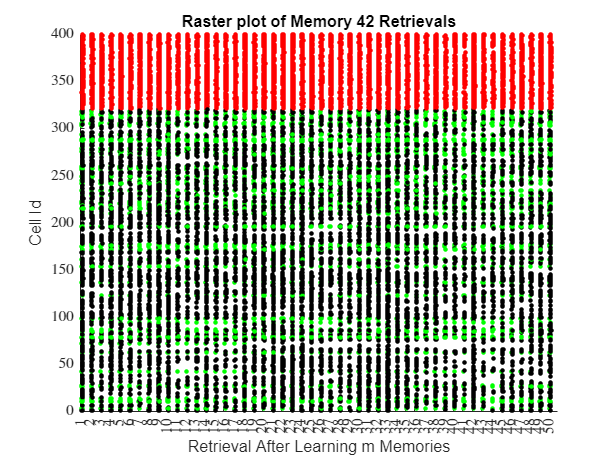

memnum = randi(n_mems);
separated = false; % separate sorting or together
eval(sprintf("firings = firings%d;", memnum))

ex_ind = firings(2, :) <= 320;
inh_ind = firings(2, :) > 320;
stim_ind = ismember(firings(2,:), stims(memnum).pattern_indices);

colors = zeros(1, size(firings, 1));
colors(ex_ind) = 0;
colors(inh_ind) = 1;
colors(stim_ind) = 2;

figure; hold on;
scatter(firings(1, :), firings(2, :), 10, colors, 'filled');
colormap([0 0 0; 1 0 0; 0 1 0]);

xticks(5:100:n_mems*100);
xticklabels(1:n_mems);
ylabel("Cell Id")
xlabel("Retrieval After Learning m Memories")
title(sprintf("Raster plot of Memory %d Retrievals", memnum))

## Sorted version of previous plot

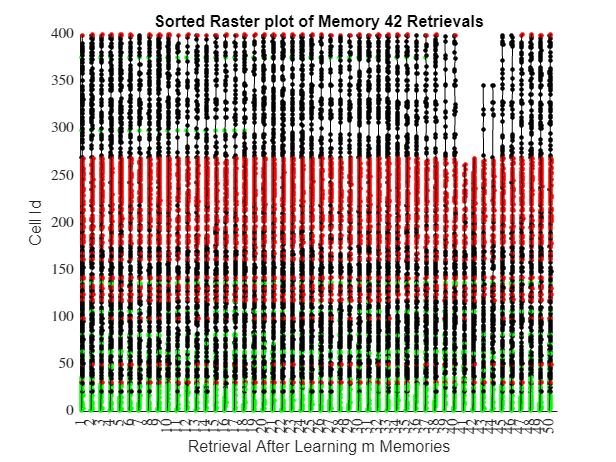

indices = (firings(1, :) > (memnum-1)*100) & (firings(1, :) < memnum*100);

order = TimeToFirstSpikeSort(firings(1,indices), firings(2,indices), separated, 400, 320);

if separated
    order([order(1:320)==0, false(1, 80)]) = (max(order(1:320))+1):320;
    order([false(1, 320), order(321:end)==0]) = (max(order(321:end))+1):400;
else
    order(order==0) = (max(order)+1):400;
end

firings(2, :) = order(firings(2, :));


figure; hold on;
scatter(firings(1, :), firings(2, :), 10, colors, "filled")

colormap([0 0 0; 1 0 0; 0 1 0]);

xticks(5:100:n_mems*100);
xticklabels(1:n_mems);
ylabel("Cell Id")
xlabel("Retrieval After Learning m Memories")
title(sprintf("Sorted Raster plot of Memory %d Retrievals", memnum))


for iter = 0:n_mems-1
    indices = (firings(1, :) > iter*100) & (firings(1, :) < (iter + 1)*100);
    local_firings = firings(:, indices);
    check = false(1,400);
   
    wavecoords = [];
    for j = 1:size(local_firings(2,:), 2)
        if ~check(local_firings(2, j))
            wavecoords = [wavecoords; [local_firings(1, j), local_firings(2, j)]];
            check(local_firings(2, j)) = true;
        end
    end
    wavecoords = wavecoords';
    [~, sortindex] = sort(wavecoords(2, :));
    wavecoords = wavecoords(:, sortindex);
    plot(wavecoords(1, :), wavecoords(2, :), 'k-')
end

## Response of the network to memory m at time t

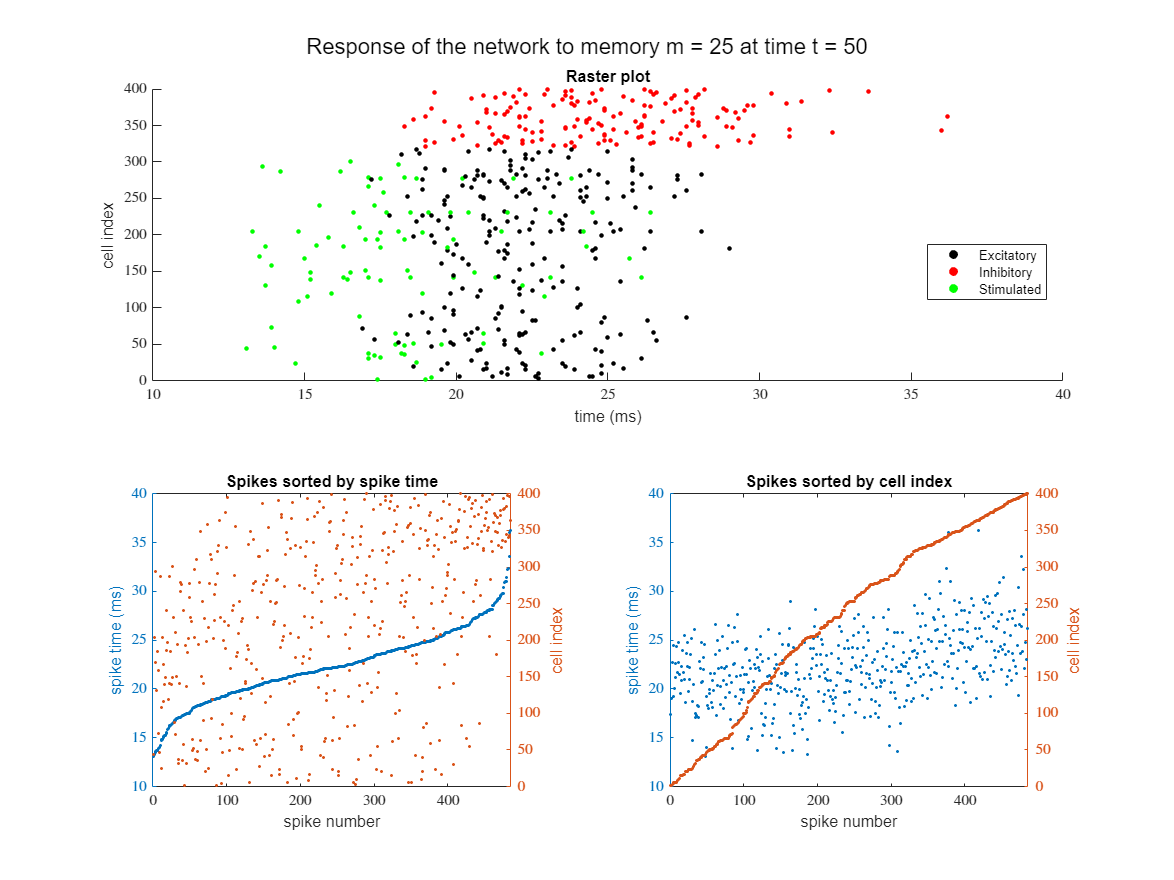

figure;
memnum = 25; t = 50; 

eval(sprintf("firings = firings%d;", memnum))
indices = firings(1, :) > (t-1)*100 & firings(1, :) < t*100;
firings = firings(:, indices);
firings(1, :) = mod(firings(1, :), 100);

f =figure(); f.Position =[50 50 1200 900]; hold on;
sgtitle(sprintf("Response of the network to memory m = %d at time t = %d", memnum, t))

subplot(2, 2, [1 2])

ex_ind = firings(2, :) <= 320;
inh_ind = firings(2, :) > 320;
stim_ind = ismember(firings(2,:), stims(memnum).pattern_indices);

colors = zeros(1, size(firings, 1));
colors(ex_ind) = 0;colors(inh_ind) = 1;colors(stim_ind) = 2;
scatter(firings(1, :), firings(2, :), 10, colors, 'filled', HandleVisibility='off');
colormap([0 0 0; 1 0 0; 0 1 0]);
xlabel("time (ms)")
ylabel("cell index")
title("Raster plot")
hold on;
scatter(nan, nan, 10, 'k', 'filled');  % Excitatory (black)
scatter(nan, nan, 10, 'r', 'filled');  % Inhibitory (red)
scatter(nan, nan, 10, 'g', 'filled');  % Stimulated (green)
legend('Excitatory', 'Inhibitory', 'Stimulated', 'Location', 'best');
hold off;

subplot(2,2,3)
title("Spikes sorted by spike time")
yyaxis left
plot(firings(1, :), '.');
ylabel("spike time (ms)")
yyaxis right
plot(firings(2, :), '.')
ylabel("cell index")
xlabel("spike number")
xlim([0 size(firings, 2)])


subplot(2,2,4)
title("Spikes sorted by cell index")
[sorted_cells, indices] = sort(firings(2, :));
yyaxis right
plot(sorted_cells, '.')
ylabel("cell index")
yyaxis left
plot(firings(1, indices), '.');
ylabel("spike time (ms)")
xlabel("spike number")
xlim([0 size(firings, 2)])

## Computing delay vectors (just first spike)

delay = 100 + 1*randn(400, 50, 50); % Ncells by m by t
dd = zeros(400, 50, 49);

for memnum = 1:50
    for t = 1:50
        eval(sprintf("firings = firings%d;", memnum))
        indices = firings(1, :) > (t-1)*100 & firings(1, :) < t*100;
        firings = firings(:, indices);
        firings(1, :) = mod(firings(1, :), 100);
        
        for cell = unique(firings(2, :))
            index = find(firings(2, :) == cell);
            if ~isempty(index)
                delay(cell, memnum, t) = firings(1, index(1));
            end 
        end
    end
end

for m = 1:n_mems
    for t = 1:n_mems-1
        dd(:, m, t) = delay(:, m, t) - delay(:, m, t+1);
    end
end

## Visualizing Spread of Delays

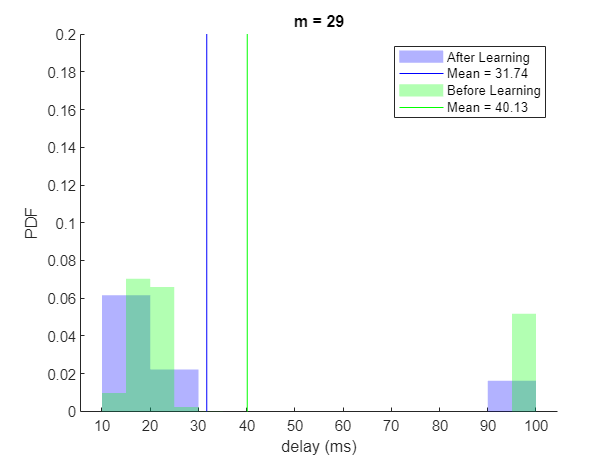

figure; hold on;
m = randi(50);

d1 = delay(1:320, m, m:min(50, m+2)); d1 = d1(d1 < 100);
d2 = delay(1:320, m, 1:m-1); d2 = d2(d2 < 100);
histogram(d1, 'FaceAlpha', 0.3, FaceColor= 'b', EdgeAlpha=0. ,EdgeColor= 'b', DisplayName= "After Learning", Normalization="pdf")
plot(mean(d1)*[1 1], [0, 0.2], 'b-', DisplayName=['Mean = ' num2str(round(mean(d1), 2))])

histogram(d2, 'FaceAlpha', 0.3, FaceColor= 'g' , EdgeAlpha= 0., EdgeColor= 'g', DisplayName= "Before Learning", Normalization="pdf")
plot(mean(d2)*[1 1], [0, 0.2], 'g-', DisplayName=['Mean = ' num2str(round(mean(d2), 2))])
% xlim([0 60])

title(['m = ' num2str(m)])
xlabel("delay (ms)")
ylabel("PDF")
legend()

## Delay vectors representation in a lower dimension  (PCA)

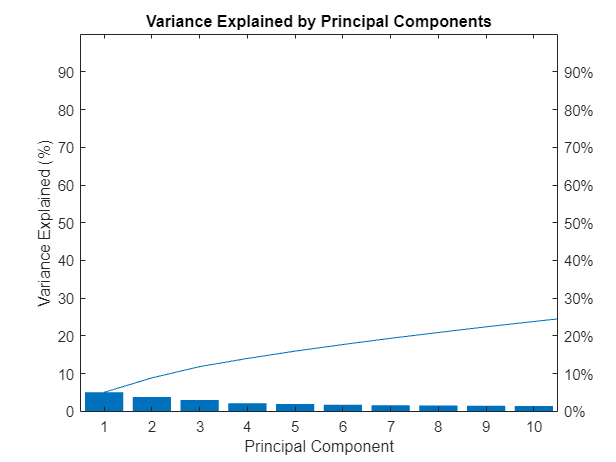

memnum = 1;
data_points = squeeze(reshape(delay(:, :, :), 400, 2500))';
[coeff, score, latent, tsquared, explained, mu] = pca(data_points);

% Plot the explained variance
figure;
pareto(explained);
xlabel('Principal Component');
ylabel('Variance Explained (%)');
title('Variance Explained by Principal Components');

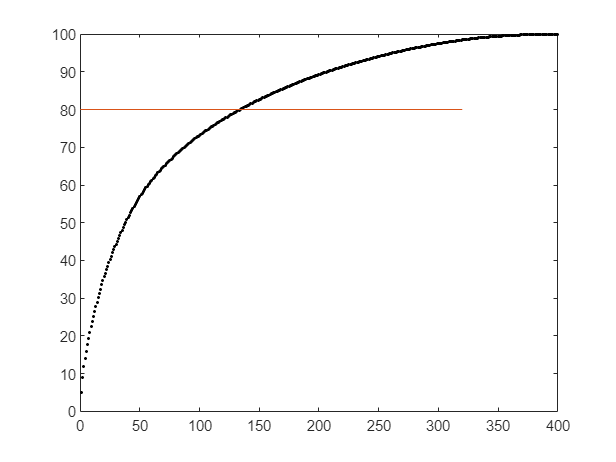

figure;plot(cumsum(explained), 'k.'); hold on; plot([0 320], [80 80])

## Scatter plot of the data in the first two principal components

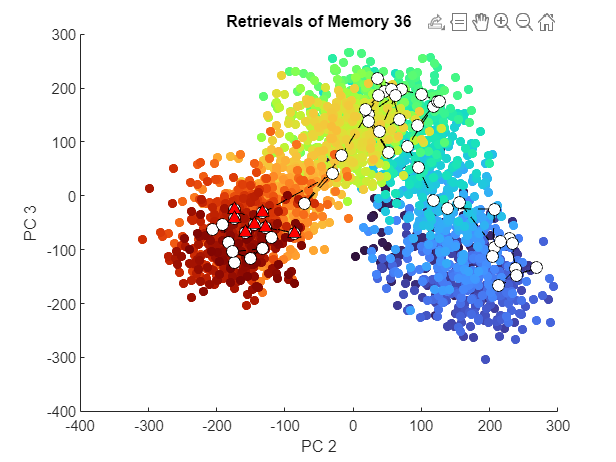


figure; hold on;
pc1 = 2; pc2 = 3; memnum = randi(50);
cmap = turbo(50);
cmap = cmap(randperm(length(cmap)), :);
colors = repmat(cmap, 50, 1);
colors = turbo(2500);
% colors = repmat(0.9* [1 1 1], 2500, 1);
% alphac = 0.7*ones(2500, 1);
% cmap = jet(50);
% for m = 1:50
%     for t = m:min(m+5, 50)
%         colors((t-1)*50+m, :) = cmap(m, :);
%         %alphac((t-1)*50+m) = 0.8;
%     end
% end
s = scatter(score(:, pc1), score(:, pc2), 40, colors, 'filled');
%s.AlphaData= alphac;
% s.AlphaData= alphac;
%s.AlphaData = ones(size(alphac))*0;
%s.MarkerEdgeColor = 'none';
% s.MarkerFaceAlpha = 'flat';

% plot(score(memnum:50:memnum*50, pc1), score(memnum:50:memnum*50, pc2), 'k--o', MarkerFaceColor=1* [1 1 1], MarkerSize=10);
% plot(score([memnum*51-50,memnum*51], pc1), score([memnum*51-50,memnum*51], pc2), 'k--');
% plot(score(memnum*51:50:end, pc1), score(memnum*51:50:end, pc2), 'k--h', MarkerFaceColor= 1*[1 1 1], MarkerSize=10);

plot(score(memnum:50:end, pc1), score(memnum:50:end, pc2), 'k--o', MarkerFaceColor=1* [1 1 1], MarkerSize=8);
d = min(50-memnum-1, 5);
plot(score(memnum*51-50:50:memnum+50*(memnum+d), pc1), score(memnum*51-50:50:memnum+50*(memnum+d), pc2), 'k^', MarkerFaceColor='r', MarkerSize=8);


% for point = memnum:50:2500
%     if ceil(point/50) >= memnum && ceil(point/50) <= memnum+6
%         text(score(point, pc1), score(point, pc2), "  " + num2str(ceil(point/50)), "FontSize", 10, 'Color', 'k')
%     end
% end
xlabel(['PC ' num2str(pc1)]);
ylabel(['PC ' num2str(pc2)]);
title(['Retrievals of Memory ' num2str(memnum)]);
refresh;

# To illustrate time delay vectors distances before and after learning respect to a global reference ($\vec{\tau}_m(t=m
)
$)

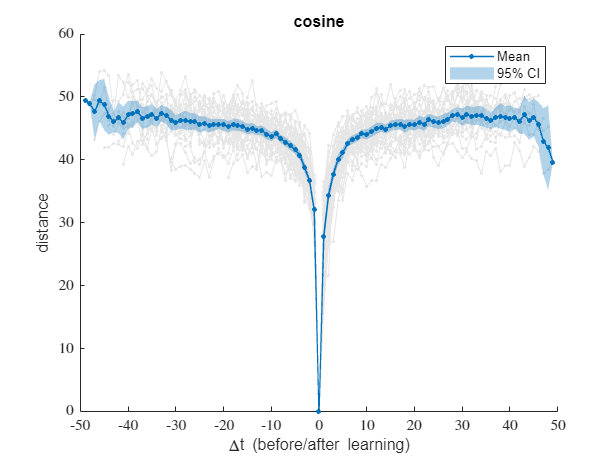

metrics  = {'euclidean', 'seuclidean', ...
                   'minkowski', 'cosine', 'correlation', 'squaredeuclidean'};
metrics = {'cosine'};

colors = lines(length(metrics));

for iter = 1:length(metrics)
    fig = figure(); hold on;

    n_timepoints = 2*n_mems-1;
    data = nan(n_mems, n_timepoints);
    
    for m = 1:n_mems
        distmat = squareform(pdist(squeeze(delay(1:400, m, :))', metrics{iter}));
        % plot((1:n_mems)-m, distmat(m, :), 'k.')
        data(m, n_mems + (1:n_mems) - m) = distmat(m, :);
    end
    data = 1-data;
    data = acos(data)*180/pi;

    xdata = (1:n_timepoints) - n_mems;
    plot(xdata, data', '.-', LineWidth=0.1, Color=0.9*[1 1 1], HandleVisibility='off') % plotting the data

    means = nanmean(data, 1);
    plot(xdata, means, '.-', MarkerSize=10, LineWidth=1, Color=colors(iter, :), DisplayName='Mean') % plotting the mean
    stderr = nanstd(data, 0, 1)./(sqrt(sum(~isnan(data), 1)));

    ci_upper = means + 1.96 * stderr; 
    ci_lower = means - 1.96 * stderr; 
    fill([xdata, fliplr(xdata)], [ci_upper, fliplr(ci_lower)], ...
     colors(iter, :), 'FaceAlpha', 0.3, 'EdgeColor', 'none', 'DisplayName', '95% CI'); % shaded CI interval
    
    xticks(-n_mems:10:n_mems)
    xlabel("\Deltat (before/after learning)")
    ylabel('distance')
    title(metrics{iter})
    
    legend()
    % xlim([-15 15])
    % saveas(fig, [metrics{iter} '.jpg'])
end

# %%

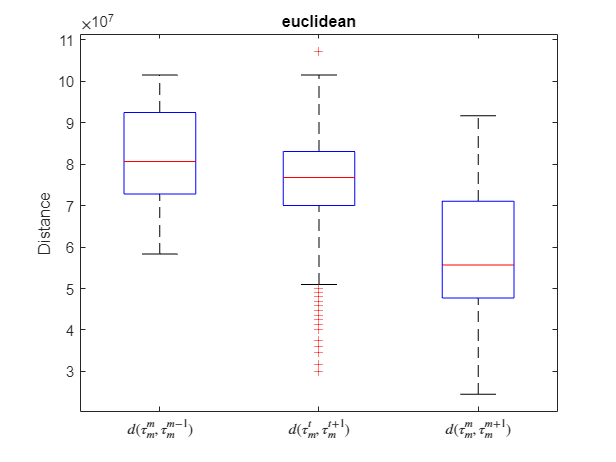

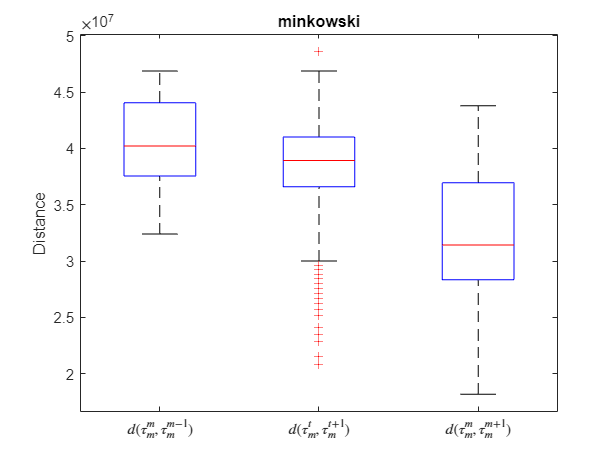

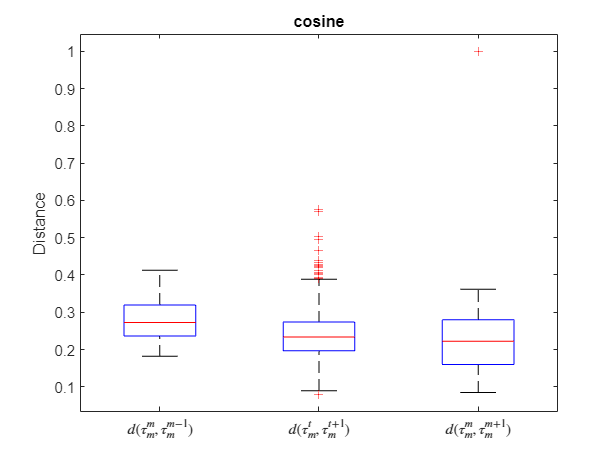

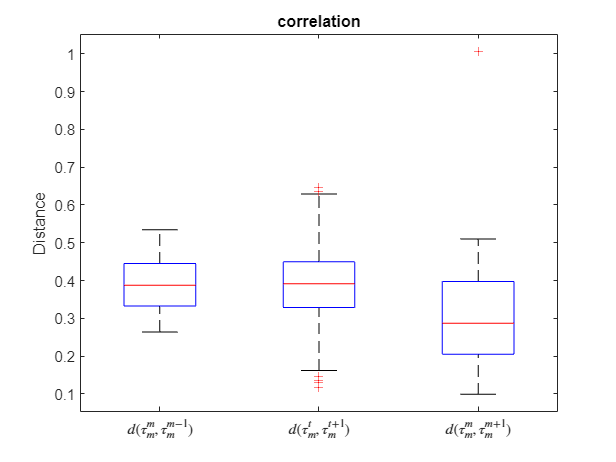

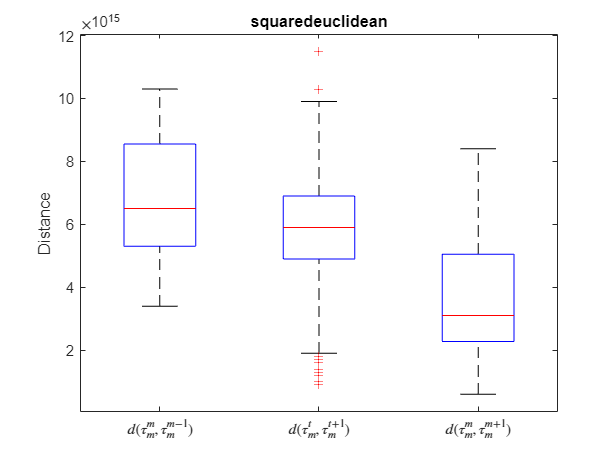


metrics = {'euclidean', 'minkowski', 'cosine', 'correlation', 'squaredeuclidean'};


for iter = 1:length(metrics)
    learning = [];
    pre = [];
    post = [];

    for m = 1:n_mems
        for t = 1:n_mems-1
            if string(metrics{iter}) == "minkowski"
                dist = pdist2(delay(1:320, m, t)', delay(1:320, m, t+1)', 'minkowski', 3);
            else
                dist = pdist2(delay(1:320, m, t)', delay(1:320, m, t+1)', metrics{iter});
            end
            if t == m -1
                learning = [learning, dist];
            elseif t == m 
                post = [post, dist];
            else
                pre = [pre, dist];
            end
        end
    end
    
    all_data = [learning, pre, post];
    group = [repmat({'$d(\tau_m^m,\tau_{m}^{m-1})$'}, 1, numel(learning)), repmat({'$d(\tau_m^t,\tau_m^{t+1})$'}, 1, numel(pre)),  repmat({'$d(\tau_m^m,\tau_m^{m+1})$'}, 1, numel(post))];
    fig = figure();
    % set(groot,'defaultAxesTickLabelInterpreter','latex');  
    boxplot(all_data, group); hold on;
    ylabel('Distance');
    xaxisproperties= get(gca, 'XAxis');
    xaxisproperties.TickLabelInterpreter = 'latex';
    title(metrics{iter});
    % saveas(fig, ['boxplot' metrics{iter} '.jpeg'])
end

# The important question is whether learning really change the time delay vector [ $\vec{\tau}_m(t=m-1)   ->  \vec{\tau}_m(t=m) $ ]

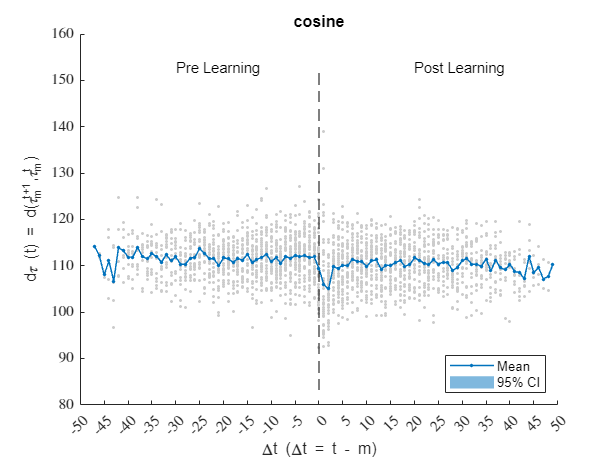

metrics = {'euclidean', 'minkowski', 'cosine', 'correlation', 'squaredeuclidean'};
metrics = {'cosine'};
colors = lines(length(metrics));

for iter = 1:length(metrics)

    dtau = nan(n_mems, 2*n_mems);
    for m = 1:n_mems
        for t = 1:n_mems-2
            if string(metrics{iter}) == "minkowski"
                dist = pdist2(dd(1:320, m, t)', dd(1:320, m, t+1)', 'minkowski', 10);
            else
                dist = pdist2(dd(1:320, m, t)', dd(1:320, m, t+1)', metrics{iter});
            end
        
            dtau(m, n_mems + t - m) = dist;
        end
    end

    fig = figure(); hold on;
    xdata = -n_mems+3:n_mems;
    dtau = dtau(:, 1:end-2);
    dtau = 1- dtau;
    dtau = acos(dtau)*180/pi;
    plot(xdata, dtau', '.', Color=0.8*[1 1 1], HandleVisibility='off')
    plot(xdata, nanmean(dtau, 1), '.-', LineWidth=1, MarkerSize=7, DisplayName='Mean', Color=colors(iter, :))
    stderr = nanstd(dtau, 1)./(sqrt(sum(~isnan(dtau), 1)));
    ci_upper = nanmean(dtau, 1) + 1.96 * stderr; 
    ci_lower = nanmean(dtau, 1) - 1.96 * stderr; 
    fill([xdata, fliplr(xdata)], [ci_upper, fliplr(ci_lower)], ...
     colors(iter, :), 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'DisplayName', '95% CI'); % shaded CI interval
    plot([0 0], [0.9*min(dtau(:)), 1.1*max(dtau(:))], 'k--', HandleVisibility='off')
    text(-30, 1.1*max(dtau(:)), 'Pre Learning')
    text(20, 1.1*max(dtau(:)), 'Post Learning')

    xticks(-n_mems:5:2*n_mems)
    xlabel("\Deltat (\Deltat = t - m)")
    ylabel("d\tau (t) = d(\tau_m^{t+1},\tau_m^t)")
    title(metrics{iter})
    legend(Location='southeast')

    % saveas(fig, [metrics{iter} '.jpeg'])
end

# For a given memory number (m), we want to find the PC that is capturing the memory

## Similarity between delay vectors

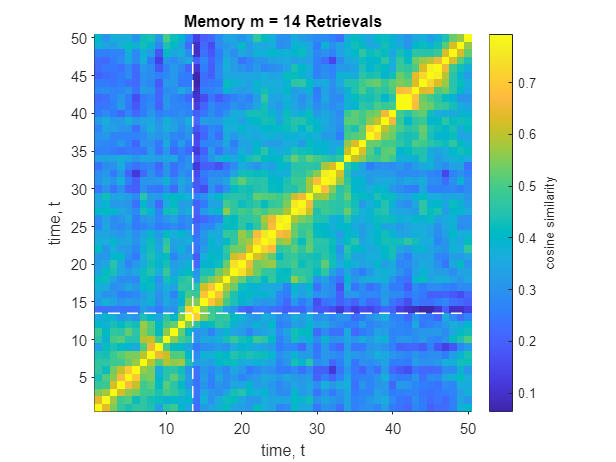

m = randi(50);

data1 = squeeze(delay(1:320, m, :))';
distmat1 = 1 - squareform(pdist(data1, "correlation"));
distmat1(logical(eye(length(distmat1)))) = max(distmat1(logical(triu(distmat1, 1))));

figure; hold on;
imshow(distmat1, [], 'InitialMagnification', 'fit')
colormap("parula")
cb = colorbar();
cb.Label.String = ['cosine' ' similarity'];
% cb.Limits = [0.5 1];
axis on

plot(m*[1, 1]-0.5, [0 50], 'w--', LineWidth=1)    
plot([0, 50], m*[1, 1]-0.5, 'w--', LineWidth=1)
xlim([0 50]+0.5)
ylim([0 50]+0.5)
title(['Memory m = ' num2str(m) ' Retrievals']);
xlabel("time, t"); ylabel("time, t");
set(gca, 'Ydir', 'Normal')

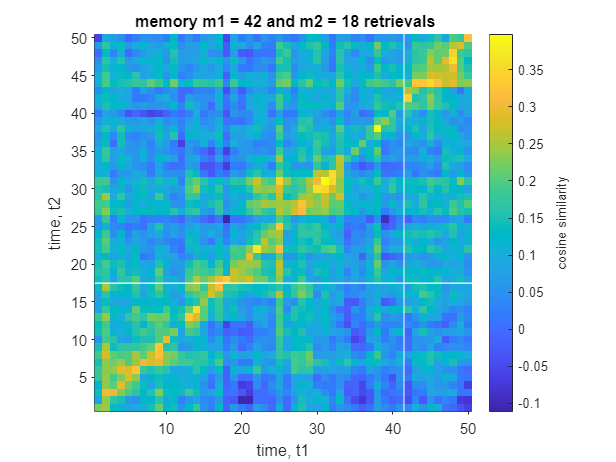

m1 = randi(50); m2 = randi(50);
data1 = squeeze(delay(1:320, m1, :))';
data2 = squeeze(delay(1:320, m2, :))';

distmat = 1 - pdist2(data1, data2, "correlation");

figure; hold on;
imshow(distmat', [], 'InitialMagnification', 'fit')
colormap("parula")
cb = colorbar();
cb.Label.String = ['cosine' ' similarity'];
% cb.Limits = [0.5 1];
axis on

plot(m1*[1, 1]-0.5, [0 50]+0.5, 'w-', LineWidth=0.8)    
plot([0, 50]+0.5, m2*[1, 1]-0.5, 'w-', LineWidth=0.7)
xlim([0 50]+0.5)
ylim([0 50]+0.5)
title([' memory m1 = ' num2str(m1) ' and m2 = ' num2str(m2) ' retrievals']);
xlabel("time, t1"); ylabel("time, t2");
set(gca, 'Ydir', 'Normal')

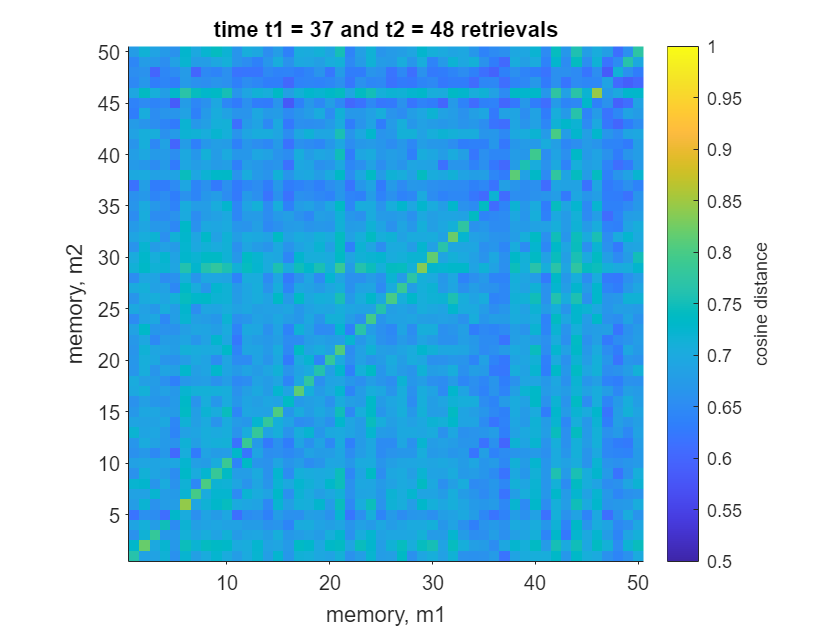

t1 = randi(50); t2 = randi(50);
data1 = squeeze(delay(1:320, :, t1))';
data2 = squeeze(delay(1:320, :, t2))';
distmat = 1-pdist2(data1, data2, "cosine");
% distmat(logical(eye(length(distmat)))) = max(distmat(logical(triu(distmat, 1))));

figure; hold on;
imshow(distmat', [0.5 1], 'InitialMagnification', 'fit')
colormap("parula")
cb = colorbar();
cb.Label.String = ['cosine' ' distance'];

% cb.Limits = [0 1];
axis on

xlim([0 50]+0.5)
ylim([0 50]+0.5)
title(['time t1 = ' num2str(t1) ' and t2 = ' num2str(t2) ' retrievals']);
xlabel("memory, m1"); ylabel("memory, m2");
set(gca, 'Ydir', 'Normal')

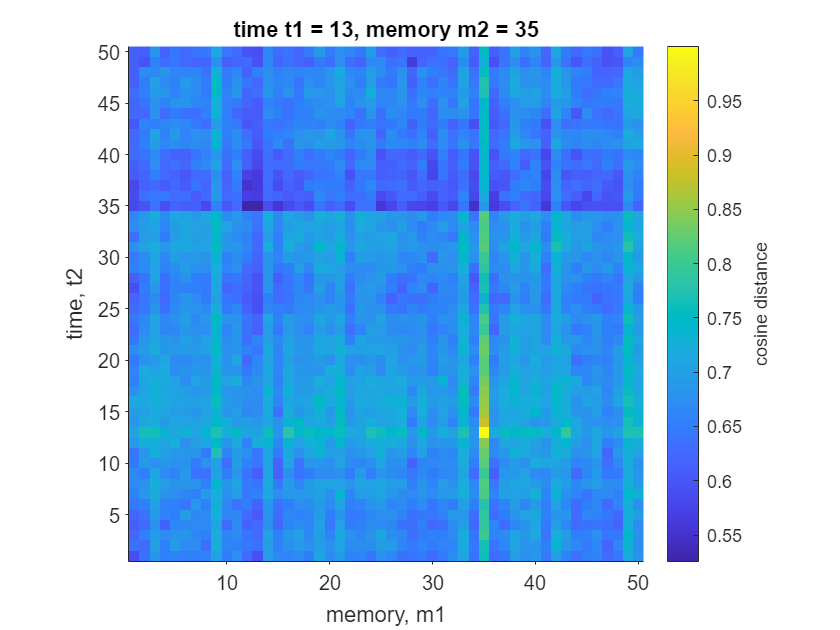

t = randi(50); m = randi(50);
data1 = squeeze(delay(1:320, :, t))';
data2 = squeeze(delay(1:320, m, :))';
distmat = 1-pdist2(data1, data2, "cosine");
% distmat(logical(eye(length(distmat)))) = max(distmat(logical(triu(distmat, 1))));

figure; hold on;
imshow(distmat', [], 'InitialMagnification', 'fit')
colormap("parula")
cb = colorbar();
cb.Label.String = ['cosine' ' distance'];
% cb.Limits = [0 1];
axis on

xlim([0 50]+0.5)
ylim([0 50]+0.5)
title(['time t1 = ' num2str(t) ', memory m2 = ' num2str(m)]);
xlabel("memory, m1"); ylabel("time, t2");
set(gca, 'Ydir', 'Normal')

norm_dd = zeros(50, 49);
for m = 1:50
    for t = 1:49
        norm_dd(m, t) = norm(delay(:,m ,t+1))/norm(delay(:, m, t));
    end
end

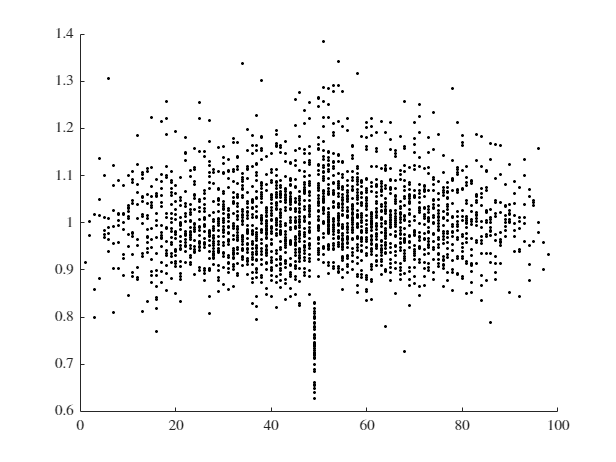

figure; hold on;
m = randi(50);
for m = 1:50
    plot((1:49) + 50 - m, norm_dd(m, :), 'k.')
        
    % scatter(49 + m-1, norm_dd(m,m-1), 'ro', 'filled')
end

% for m = 1:50
%     plot((1:49)+50-m, norm_dd(m, :), 'k.')
% end

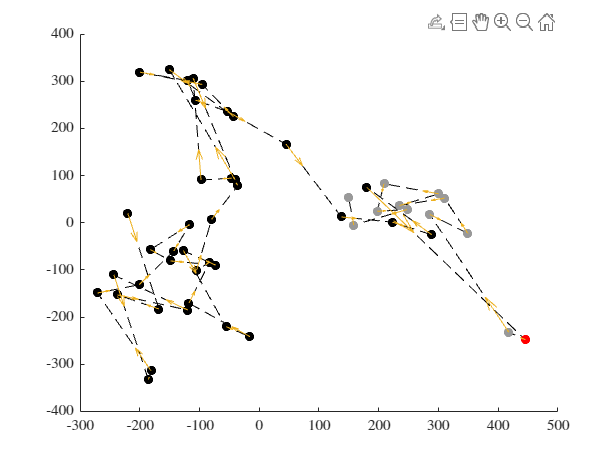

m = randi(50);
data_points = squeeze(reshape(delay(:, m, :), 400, 50))';
[coeff, score, latent, tsquared, explained, mu] = pca(data_points);
colors = [zeros(m-1, 3);[1 0 0]; 0.6*ones(n_mems-m, 3)];
figure;hold on; pc1 = 1; pc2 = 2;
plot(score(:, pc1), score(:, pc2), 'k--')
scatter(score(:, pc1), score(:, pc2), 40, colors, 'filled')
quiver(score(1:end-1, pc1), score(1:end-1, pc2), score(2:end, pc1)-score(1:end-1, pc1), score(2:end, pc2)-score(1:end-1, pc2))